# 类脑音频识别

## 准备音频数据

run('music_genre_fMRI\process_music.mlx');

## 训练音频分类网络

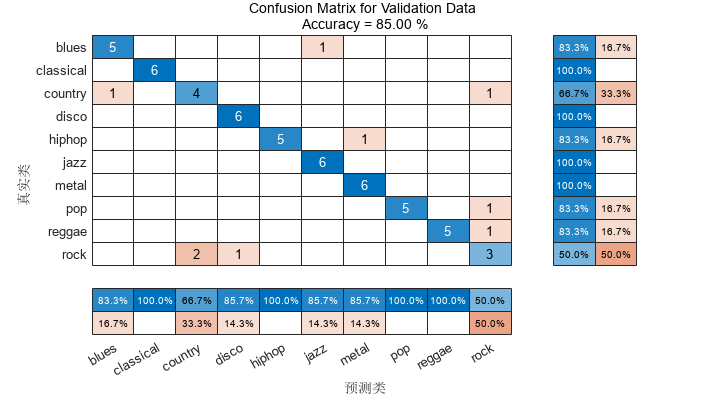

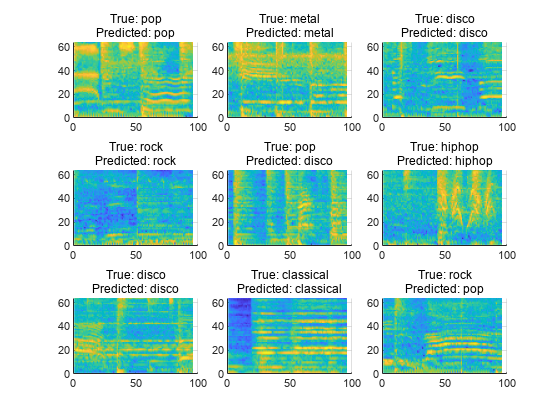

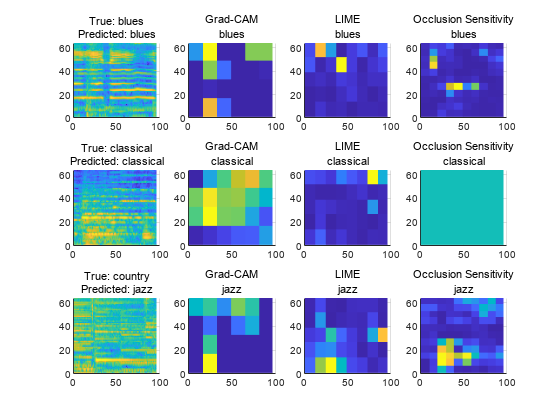

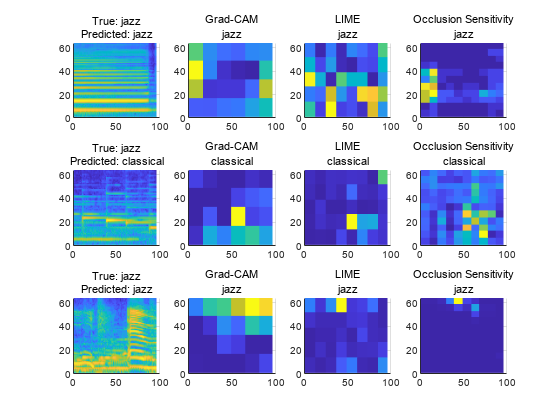

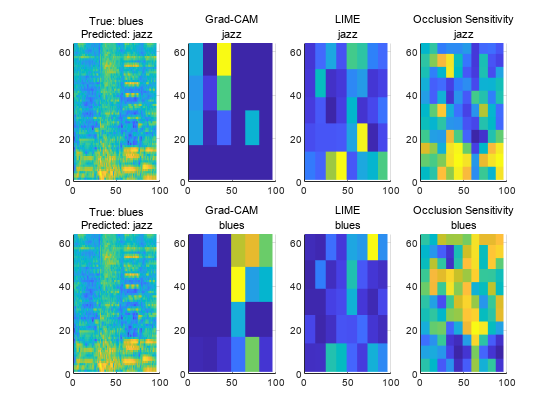

warning off
run('genre_classification.mlx');

warning on


## 大脑激活数据分析

% TODO
% spm
run('music_genre_fMRI/preprocess/main.m')

## 提取对应音频的大脑激活和深度模型激活

run('get_fMRI_activation.mlx');

Process directory D:\buffer\data\brain\auditory\music_genre_fMRI\preprocess\ds003720-download\sub-001\


错误使用 spm_vol>spm_vol_hdr
File "D:\buffer\data\brain\auditory\music_genre_fMRI\preprocess\ds003720-download\sub-001\func\swrsub-001_task-Training_run-01_bold.nii" does not
exist.

出错 spm_vol (第 61 行)
        v = spm_vol_hdr(deblank(P(i,:)));

出错 get_fMRI_activation (第 30 行)
        cur_vol_infs 

## 大脑激活和模型激活的回归和预测

run('analysis_FeaturePrediction'); % 得出类脑相似性分数

## 论文生成

% latex
cc
run('../../utils/init_matlab.mlx');
cc
cd('latex');
latex_cmd = [fullfile(latex_exe_dir, 'pdflatex.exe') ' -synctex=1 -interaction=nonstopmode ban.tex']
system(latex_cmd);
winopen('ban.pdf')
init_robot

测试


% BUTTON1_MASK（鼠标左键），BUTTON2_MASK（鼠标中键）；BUTTON3_MASK（鼠标右键）
robot.keyPress    (java.awt.event.KeyEvent.VK_CONTROL);
robot.mousePress  (java.awt.event.InputEvent.BUTTON1_MASK);
robot.mouseRelease(java.awt.event.InputEvent.BUTTON1_MASK);
robot.keyRelease  (java.awt.event.KeyEvent.VK_CONTROL);

% robot.mousePress(KeyEvent.VK_CONTROL);
% robot.mousePress(KeyEvent.VK_2);
% robot.mouseRelease(KeyEvent.VK_CONTROL);
% robot.mouseRelease(KeyEvent.VK_2);
